# 1. Local and global space-charge test - MATLAB

Run spacecharge_test.ipynb, then Run All here, then compare_results.ipynb. This readable .m and its companion .mlx contain the same calculation. MATLAB independently builds its reference/grid, entrance beam, prefill and prescribed in-domain profiles. No Python-calculated fields are imported. No cavity fields, particle tracking or nonlinear iterations are computed.

test_directory=fileparts(mfilename('fullpath'));
if ~isfile(fullfile(test_directory,'spacecharge_test.m'))
    test_file=matlab.desktop.editor.getActiveFilename;
    test_directory=fileparts(test_file);
    if ~isfile(fullfile(test_directory,'spacecharge_test.m'))
        test_directory=fileparts(which('spacecharge_test.m'));
    end
end
input_file=fullfile(test_directory,'inputs.mat');
assert(isfile(input_file), ...
    'Cannot find inputs.mat at: %s\nRun spacecharge_test.ipynb first.',input_file);
load(input_file);
assert(Nt>=16 && Ns>=1 && Ns<Nt/2 && nn>=1);
assert(rc~=0 && yd==0 && rm1>=0 && rm1<rm2 && rm2<=rc);
assert(factor>=0 && factorregion>=0 && fillfactor>=0 && DCSPfactor>=0);
assert(speed_drop>=0 && speed_drop<1 && modulation_growth>=0);

## 2. Reference beam, grid and source windows - Original lines 45-97

Original constants/arithmetic, including Lsb initialization. The only syntax correction removes the stray N in Nesz=zeros(... )N.

CALCULATE THE REFERENCE PAMAMETER

Nt = double(Nt)

Nt = 128


Iz0=1/2/pi*2*pi/Nt*sum(Izt(Y0)); % A, araverge emission current
I0=abs(Iz0);
U0=1/2/pi*2*pi/Nt*sum(Izt(Y0).*Ut(Y0))/Iz0;% kV, average emission voltage

% constant
c=299792458;  % m/s, light speed
etom=-1.7588E11;  % C/kg, charge to mass of electron
eta0=4E-7*pi*c; % ohm, wave impendance of TEM

esign=sign(-etom); % for negative charged paticles, esign=1; for postive charged particles, esign=-1
etom=abs(etom);

etom = double(etom);
c    = double(c);
U0   = double(U0);

s=(1-(1+etom/c/c*U0*1E3)^(-2))^(1/2); % ve0/c
vetoc=(1-(1+etom/c/c*Ut*1E3).^(-2)).^(1/2); % vet/c
vn1=0*vetoc;
vn1(Y0)=s./vetoc(Y0); % ve0/ve(t) at the entrance


w=2*pi*f*1E9;  % rad/s, angular frequency of operating
w0=2*pi*f0*1E9;  % rad/s, angular frequency of resonant
k0=w0/c/1000;   % 1/mm,  wave number at resonant freqency
Lsb=pi*ones(1,Nc); % phaseshift beta0*Ls from the entrance of output cavity at resonant freqency

gama=1+etom*U0*1000/c/c; % Lorentz factor
betae=w/c/s/1000;  % 1/mm, betae at operating freqency

Nz = double(Nz);
dz=2*pi/betae/Nz;  % mm,

dz=L/floor(L/dz); % mm, increment of z
dz = double(dz);
zi=(z0:dz:z0+L)'; % mm, z position sequence

rcvs=interp1(rcv(1,:),rcv(2,:)*rc,zi,'linear','extrap'); % mm, tunnel radius sequence

if rc~=0  % for cylindrical beam
    dN=floor(factorregion*rc/2.40483/dz); % N dz interval is included to calculate the local SP
    Nesz=zeros(length(zi),2); % TEST ONLY: removed stray N syntax error
    for k=1:length(zi)
        Nesz(k,1)=max(1,k-dN); % min order of interval
        Nesz(k,2)=min(length(zi),k+dN); % max order of interval
    end
else  % for sheet beam

end
assert(all(rcvs>=rm2));
prefill_enabled=factor~=0 && fillfactor~=0 && DCSPfactor~=0;
assert(~(prefill_enabled && dN==1), ...
    'Enabled prefill with dN=1 has an original MATLAB sum-dimension issue; see test/README.md.');

## 3. Coordinates, entrance harmonics and plasma frequency - Original 132-159

z=betae*zi; % normalized z position
dt=betae*dz; % normalized time step & normalized position step, in real time step=position step/injecting velocity of electron


Iz=zeros(length(z),Ns);
QQ=zeros(length(z),Ns);

% intial value given
Y=Y0;
IzDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0)*ones(length(z),1); % normalized DC current along the axis
for k=1:Ns
    Iz(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)))*ones(length(z),1); % normalized,intial modulated current of 1st harmonic
end

QQDC=1/2/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*vn1(Y))*ones(length(z),1); % DC charge density along axis
for k=1:Ns
    QQ(:,k)=1i/pi*(2*pi/Nt)*sum(Izt(Y)/Iz0.*exp(-k*1i*tn1(Y)).*vn1(Y))*ones(length(z),1); % normalized,intial modulated charged density
end

if rc~=0
    wp=factor*sqrt(I0*etom/pi/((rm2*1E-3)^2-(rm1*1E-3)^2)/(1/c/eta0)/c/s); % rad/s, plasma angular frquency
else
    
end

effe=0*ones(length(z),1); % if all electron reflected, the efficiency will be 100%
vez=1*ones(length(z),1); % ve/ve0
gamaz=(1-(vez*s).^2).^(-1/2);

## 4. Fixed upstream prefill - Original lines 161-179

The original arithmetic and source-phase convention are preserved. TEST EXECUTION ADAPTER: parfor -> for, without a parallel pool. TEST DIAGNOSTICS: Python also retains source arrays with disabled prefill. Repeat original lines 166-169 in that case only; the field stays zero.

if factor==0 || fillfactor==0 || DCSPfactor==0
    zp=repmat([z(1)-betae*dz:-betae*dz:z(1)-betae*dz*dN].',1,Ns+1);
    [Nfill,~]=size(zp);
    gamazp=[ones(Nfill,1),repmat(gamaz(1),Nfill,Ns)];
    QQfill=[repmat(QQDC(1),Nfill,1) repmat(QQ(1,:),Nfill,1).*exp(-1i*repmat([1:Ns],Nfill,1).*(z(1)-zp(:,2:end)))];
end
% Now we compute a prefill space charge
Esz00=zeros(length(z),1+Ns);

if factor~=0 && fillfactor~=0 && DCSPfactor~=0
    % For DC beam filled ahead of the entrance
    zp=repmat([z(1)-betae*dz:-betae*dz:z(1)-betae*dz*dN].',1,Ns+1);
    [Nfill,~]=size(zp);
    gamazp=[ones(Nfill,1),repmat(gamaz(1),Nfill,Ns)];
    QQfill=[repmat(QQDC(1),Nfill,1) repmat(QQ(1,:),Nfill,1).*exp(-1i*repmat([1:Ns],Nfill,1).*(z(1)-zp(:,2:end)))];
    if rc~=0  % for cylindrical beam
        for kk=1:length(z)
            Esz00(kk,:)=esign*dz*betae*sum(-QQfill.*sign(z(kk)-zp)/2*wp^2/w^2*(gama+1)/gama/gama.*(exp(-2.40483*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/2.40483*(rm2*besselj(1,2.40483*rm2/rc)-rm1*besselj(1,2.40483*rm1/rc))/besselj(1,2.40483))^2+exp(-5.52008*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/5.52008*(rm2*besselj(1,5.52008*rm2/rc)-rm1*besselj(1,5.52008*rm1/rc))/besselj(1,5.52008))^2+exp(-8.65373*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/8.65373*(rm2*besselj(1,8.65373*rm2/rc)-rm1*besselj(1,8.65373*rm1/rc))/besselj(1,8.65373))^2+exp(-11.79153*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/11.79153*(rm2*besselj(1,11.79153*rm2/rc)-rm1*besselj(1,11.79153*rm1/rc))/besselj(1,11.79153))^2+exp(-14.93092*gamazp.*abs(zp-z(kk))/betae/rc)/(rm2^2-rm1^2)*(2/14.93092*(rm2*besselj(1,14.93092*rm2/rc)-rm1*besselj(1,14.93092*rm1/rc))/besselj(1,14.93092))^2));
        end
        
    else   % for sheet beam

    end
    
end

## 5. Fixed radial mode factors - Original lines 191-197

if rc~=0  % for cylindrical beam
    Eszr1=(2/2.40483*(rm2*besselj(1,2.40483*rm2./rcvs)-rm1*besselj(1,2.40483*rm1./rcvs))/besselj(1,2.40483)).^2;
    Eszr2=(2/5.52008*(rm2*besselj(1,5.52008*rm2./rcvs)-rm1*besselj(1,5.52008*rm1./rcvs))/besselj(1,5.52008)).^2;
    Eszr3=(2/8.65373*(rm2*besselj(1,8.65373*rm2./rcvs)-rm1*besselj(1,8.65373*rm1./rcvs))/besselj(1,8.65373)).^2;
    Eszr4=(2/11.79153*(rm2*besselj(1,11.79153*rm2./rcvs)-rm1*besselj(1,11.79153*rm1./rcvs))/besselj(1,11.79153)).^2;
    Eszr5=(2/14.93092*(rm2*besselj(1,14.93092*rm2./rcvs)-rm1*besselj(1,14.93092*rm1./rcvs))/besselj(1,14.93092)).^2;
end
Eszr=[Eszr1,Eszr2,Eszr3,Eszr4,Eszr5]; % TEST ONLY: Python's five-column layout

## 6. TEST ONLY: prescribed in-domain beam after prefill initialization

These profiles exercise the update inputs; they are not beam dynamics. Constant speed: exp(-i*k*(z-z(1))). Synthetic: prescribed speed/amplitude.

if strcmp(beam_profile,'constant_speed') || strcmp(beam_profile,'synthetic')
    amplitude=ones(length(z),1);
    phase_distance=z-z(1);
    if strcmp(beam_profile,'synthetic')
        x=(zi-zi(1))/L;
        vez=1-speed_drop*x;
        gamaz=(1-(s*vez).^2).^(-1/2);
        amplitude=1+modulation_growth*sin(pi*x).^2;
        phase_distance=cumtrapz(z,1./vez);
    end
    phase_advance=exp(-1i*phase_distance*(1:Ns));
    Iz=Iz.*amplitude.*phase_advance;
    QQ=QQ.*amplitude.*phase_advance./vez;
    QQDC=QQDC./vez;
else
    assert(strcmp(beam_profile,'initial_guess'));
end

## 7. Both update branches - Original lines 314-347

Same prescribed beam, first local then global. No outer iteration. Formula arithmetic is unchanged; parfor is replaced by for. TEST SYNTAX ADAPTER: original lines 322-323 split the .* operator across a continuation (gama. ... then *(...)). Move the dot next to the *. Test scenarios 2/3 independently check first-iteration and disabled reset.

nn_input=nn;
factor_input=factor;
for test_scenario=1:3
    nn=nn_input;
    factor=factor_input;
    if test_scenario==2
        nn=1;
    elseif test_scenario==3
        factor=0;
    end
    for SCmethod=[0,1]
        % Nonzero old values: the original block must clear all three arrays.
        Esz=(1+2i)*ones(length(z),Ns);
        Esz0=(1+2i)*ones(length(z),1);
        Esztotal=(1+2i)*ones(length(z),Ns+1);
    % space charge field calculated
    Esz=zeros(length(z),Ns);
    Esz0=zeros(length(z),1);
    Esztotal=[Esz0,Esz];
    QQtotal=[QQDC,QQ];
    if nn~=1 && factor~=0 && SCmethod~=0
        if rc~=0  % for cylindrical beam
            for kk=1:length(z) % TEST ONLY: serial execution
                Esztotal(kk,:)=esign*dz*betae*sum(-QQtotal(Nesz(kk,1):Nesz(kk,2),:).*[sign(z(kk)-z(Nesz(kk,1):Nesz(kk,2)))/2*wp^2/w^2*(gama+1)/gama/gama ...
                    .*(exp(-2.40483*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr1(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-5.52008*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr2(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-8.65373*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr3(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-11.79153*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr4(Nesz(kk,1):Nesz(kk,2)) ...
                    +exp(-14.93092*1.*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr5(Nesz(kk,1):Nesz(kk,2)))...
                    ,repmat(sign(z(kk)-z(Nesz(kk,1):Nesz(kk,2)))/2*wp^2/w^2*(gama+1)/gama/gama.*(exp(-2.40483*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr1(Nesz(kk,1):Nesz(kk,2))+exp(-5.52008*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr2(Nesz(kk,1):Nesz(kk,2))+exp(-8.65373*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr3(Nesz(kk,1):Nesz(kk,2))+exp(-11.79153*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr4(Nesz(kk,1):Nesz(kk,2))+exp(-14.93092*gamaz(Nesz(kk,1):Nesz(kk,2)).*abs(z(Nesz(kk,1):Nesz(kk,2))-z(kk))/betae./rcvs(Nesz(kk,1):Nesz(kk,2)))/(rm2^2-rm1^2).*Eszr5(Nesz(kk,1):Nesz(kk,2))),1,Ns)]);
            end
            
        else

        end
        Esz=Esztotal(:,2:(Ns+1))+fillfactor*Esz00(:,2:(Ns+1));
        Esz0=DCSPfactor*(Esztotal(:,1)+fillfactor*Esz00(:,1));
    elseif nn~=1 && factor~=0 && SCmethod==0
        if rc~=0  % for cylindrical beam
            for k=1:Ns
                Esz(:,k)=-esign*1i*Iz(:,k)/k*wp^2/w^2*(gama+1)/gama/gama*1/(rm2^2-rm1^2).*(Eszr1./(1+(2.40483/k/rc/betae*vez.*gamaz).^2)+Eszr2./(1+(5.52008/k/rc/betae*vez.*gamaz).^2)+Eszr3./(1+(8.65373/k/rc/betae*vez.*gamaz).^2)+Eszr4./(1+(11.79153/k/rc/betae*vez.*gamaz).^2)+Eszr5./(1+(14.93092/k/rc/betae*vez.*gamaz).^2));
            end
        else

        end
    else
        % do nothing
        
    end
        if test_scenario==1
            if SCmethod==0
                Esz_local=Esz;
                Esz0_local=Esz0;
                Esztotal_local=Esztotal;
            else
                Esz_global=Esz;
                Esz0_global=Esz0;
                Esztotal_global=Esztotal;
            end
        else
            assert(all(Esz==0,'all') && all(Esz0==0,'all') && all(Esztotal==0,'all'));
        end
    end
end
nn=nn_input;
factor=factor_input;
SCmethods=[0,1];

## 8. TEST ONLY: reconstructed field snapshots and summary

Imaginary-part RF convention; DC included separately. Fields dimensionless.

phase=exp(1i*(1:Ns)'*theta);
E_local=real(Esz0_local)+imag(Esz_local*phase);
E_global=real(Esz0_global)+imag(Esz_global*phase);
fprintf('Case: %s; profile: %s; nn=%d; grid nodes=%d; dN=%d\n', ...
    case_name,beam_profile,nn,length(z),dN);

Case: modulated; profile: constant_speed; nn=2; grid nodes=3806; dN=52


disp(table((0:Ns)',max(abs([Esz0_local,Esz_local]),[],1).', ...
    max(abs([Esz0_global,Esz_global]),[],1).', ...
    'VariableNames',{'Harmonic','Max_local','Max_global'}));

    Harmonic    Max_local     Max_global
    ________    __________    __________

       0                 0      0.021745
       1        0.00065266     0.0030809
       2        0.00063567     0.0015205
       3        2.0179e-18    3.2874e-18
       4         4.759e-18    5.9826e-18
       5        3.2628e-18    3.3961e-18
       6        5.0858e-18     5.108e-18
       7        3.9039e-18    3.9526e-18
       8        6.9736e-18    7.1327e-18



disp('Local/global differences are model diagnostics, not translation errors.');

Local/global differences are model diagnostics, not translation errors.


## 9. TEST ONLY: beam and geometry plots

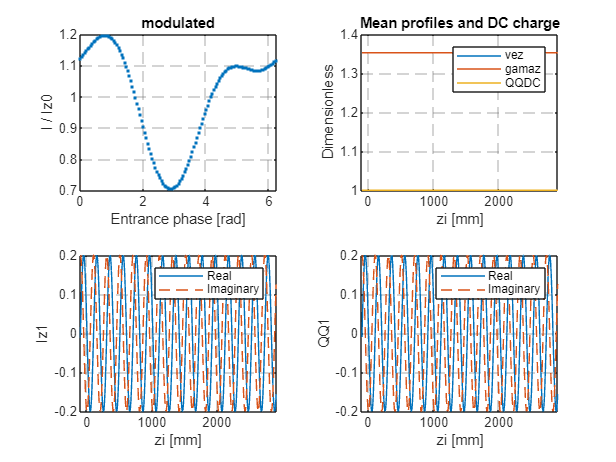

style_axes=@(fig) set(findall(fig,'Type','axes'), ...
    'XGrid','on','YGrid','on','GridLineStyle','--', ...
    'GridColor',[0.5 0.5 0.5],'GridAlpha',0.45);
figure('Name','Prescribed beam');
tiledlayout(2,2);
nexttile; plot(mod(tn1,2*pi),Izt/Iz0,'.'); xlabel('Entrance phase [rad]');
ylabel('I / Iz0'); title(case_name,'Interpreter','none');
nexttile; plot(zi,vez,zi,gamaz,zi,QQDC); legend('vez','gamaz','QQDC');
xlabel('zi [mm]'); ylabel('Dimensionless'); title('Mean profiles and DC charge');
nexttile; plot(zi,real(Iz(:,1)),zi,imag(Iz(:,1)),'--');
xlabel('zi [mm]'); ylabel('Iz1'); legend('Real','Imaginary');
nexttile; plot(zi,real(QQ(:,1)),zi,imag(QQ(:,1)),'--');
xlabel('zi [mm]'); ylabel('QQ1'); legend('Real','Imaginary');
style_axes(gcf);

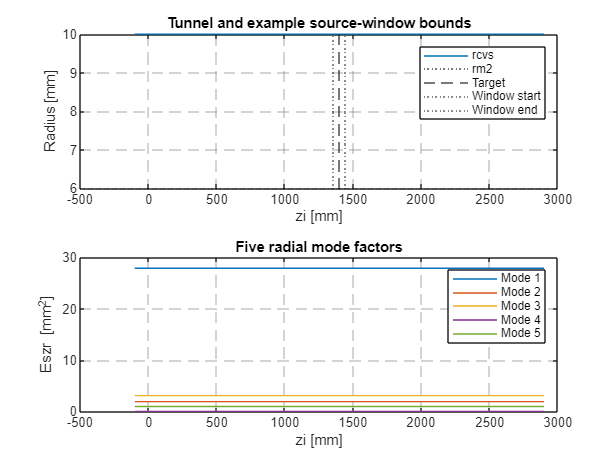


figure('Name','Geometry and radial mode factors');
tiledlayout(2,1);
nexttile; plot(zi,rcvs); hold on; yline(rm2,'k:');
target=floor(length(z)/2)+1;
xline(zi(target),'k--');
xline(zi(Nesz(target,1)),':'); xline(zi(Nesz(target,2)),':');
xlabel('zi [mm]'); ylabel('Radius [mm]'); title('Tunnel and example source-window bounds');
legend('rcvs','rm2','Target','Window start','Window end');
nexttile; plot(zi,Eszr); xlabel('zi [mm]'); ylabel('Eszr [mm^2]');
title('Five radial mode factors'); legend(compose('Mode %d',1:5));
style_axes(gcf);

## 10. TEST ONLY: local/global fields and prefill contributions

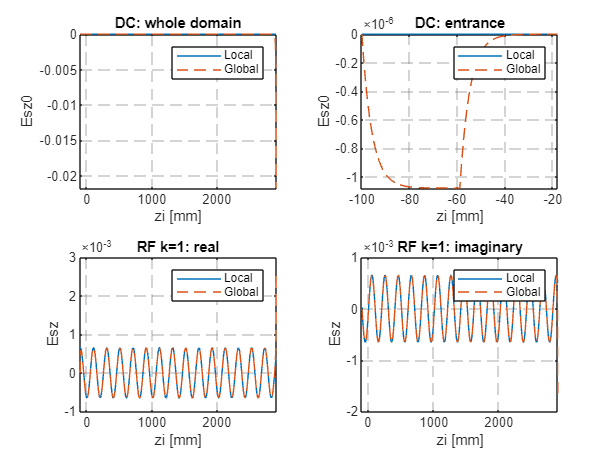

figure('Name','Local versus global field coefficients');
tiledlayout(2,2);
nexttile; plot(zi,real(Esz0_local),zi,real(Esz0_global),'--');
title('DC: whole domain'); xlabel('zi [mm]'); ylabel('Esz0'); legend('Local','Global');
nexttile; plot(zi,real(Esz0_local),zi,real(Esz0_global),'--');
xlim([zi(1),min(zi(end),zi(1)+max(4*rc,2*dN*dz))]);
title('DC: entrance'); xlabel('zi [mm]'); ylabel('Esz0'); legend('Local','Global');
nexttile; plot(zi,real(Esz_local(:,1)),zi,real(Esz_global(:,1)),'--');
title('RF k=1: real'); xlabel('zi [mm]'); ylabel('Esz'); legend('Local','Global');
nexttile; plot(zi,imag(Esz_local(:,1)),zi,imag(Esz_global(:,1)),'--');
title('RF k=1: imaginary'); xlabel('zi [mm]'); ylabel('Esz'); legend('Local','Global');
style_axes(gcf);

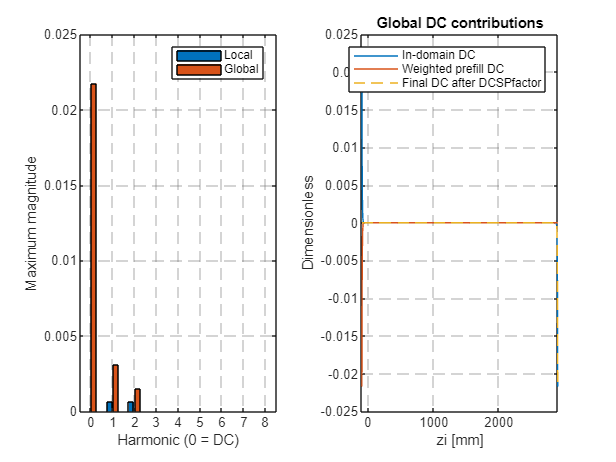


figure('Name','All harmonics and global DC components');
tiledlayout(1,2);
nexttile; bar(0:Ns,[max(abs([Esz0_local,Esz_local]),[],1).', ...
    max(abs([Esz0_global,Esz_global]),[],1).']);
xlabel('Harmonic (0 = DC)'); ylabel('Maximum magnitude'); legend('Local','Global');
nexttile; plot(zi,real(Esztotal_global(:,1)),zi,fillfactor*real(Esz00(:,1)), ...
    zi,real(Esz0_global),'--');
xlabel('zi [mm]'); ylabel('Dimensionless'); title('Global DC contributions');
legend('In-domain DC','Weighted prefill DC','Final DC after DCSPfactor');
style_axes(gcf);

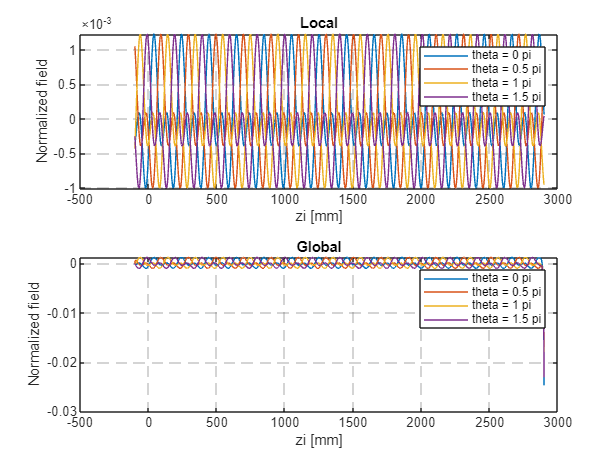


figure('Name','Instantaneous space-charge snapshots');
tiledlayout(2,1);
nexttile; plot(zi,E_local); title('Local'); xlabel('zi [mm]'); ylabel('Normalized field');
legend(compose('theta = %.2g pi',theta/pi));
nexttile; plot(zi,E_global); title('Global'); xlabel('zi [mm]'); ylabel('Normalized field');
legend(compose('theta = %.2g pi',theta/pi));
style_axes(gcf);

## 11. TEST ONLY: dimensions, finiteness and prefill combination

assert(isequal(size(Eszr),[length(z),5]) && all(Eszr>=0,'all'));
assert(isequal(size(Esz_local),[length(z),Ns]) && isequal(size(Esz_global),size(Esz_local)));
assert(isequal(size(Esztotal_global),[length(z),Ns+1]));
assert(all(isfinite(Esz_local),'all') && all(isfinite(Esz_global),'all'));
assert(all(isfinite(Esz0_global),'all') && all(isfinite(Esztotal_global),'all'));
assert(all(Esz0_local==0) && all(Esztotal_local==0,'all'));
assert(all(abs(imag(Esz0_global))<=1e-12) && all(abs(imag(Esz00(:,1)))<=1e-12));
if nn==1 || factor==0
    assert(all(Esz_local==0,'all') && all(Esz_global==0,'all'));
    assert(all(Esz0_global==0,'all') && all(Esztotal_global==0,'all'));
else
    expected=Esztotal_global(:,2:end)+fillfactor*Esz00(:,2:end);
    assert(all(abs(Esz_global-expected)<=1e-12+1e-10*abs(expected),'all'));
    expected=DCSPfactor*(Esztotal_global(:,1)+fillfactor*Esz00(:,1));
    assert(all(abs(Esz0_global-expected)<=1e-12+1e-10*abs(expected)));
end
disp('PASS: MATLAB local/global calculations, dimensions, combination and disabled/reset checks.');

PASS: MATLAB local/global calculations, dimensions, combination and disabled/reset checks.


## 12. Export this test's MATLAB results

Original one-based inclusive Nesz is retained. The comparator translates only the first column of Python's zero-based/exclusive-stop Nesz.

save(fullfile(test_directory,'matlab_results.mat'), ...
    'Iz0','I0','U0','s','vetoc','vn1','gama', ...
    'w','betae','dz','zi','z','dt','rcvs','dN','Nesz', ...
    'IzDC','Iz','QQDC','QQ','vez','gamaz', ...
    'wp','zp','gamazp','QQfill','Esz00','Eszr', ...
    'Esz_local','Esz0_local','Esztotal_local','Esz_global','Esz0_global','Esztotal_global', ...
    'Nfill','SCmethods','E_local','E_global','theta', ...
    'Nt','Ns','nn','factor','factorregion','fillfactor','DCSPfactor','speed_drop','modulation_growth', ...
    'case_name','beam_profile','run_id','-v7');
fprintf('Saved: %s\n',fullfile(test_directory,'matlab_results.mat'));

Saved: C:\Users\lsito\Desktop\PyKlyC\pyKlyC\test\6.spacecharge_test\matlab_results.mat


disp('Next: run compare_results.ipynb.');

Next: run compare_results.ipynb.
